Seeeing what kids of effect that performing changes to the color channel has on the images when recombind

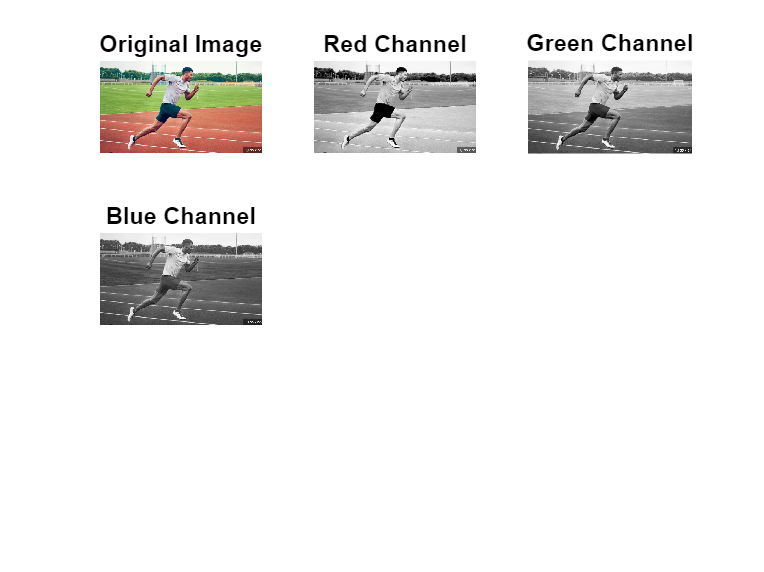

% Read the image
img = imread('running.PNG');

% Split the image into its RGB channels
R = img(:,:,1);
G = img(:,:,2);
B = img(:,:,3);

% Display the original image and its RGB channels
figure;
subplot(3,3,1);
imshow(img);
title('Original Image');
subplot(3,3,2);
imshow(R);
title('Red Channel');
subplot(3,3,3);
imshow(G);
title('Green Channel');
subplot(3,3,4);
imshow(B);
title('Blue Channel');

histeq applied to the red channel

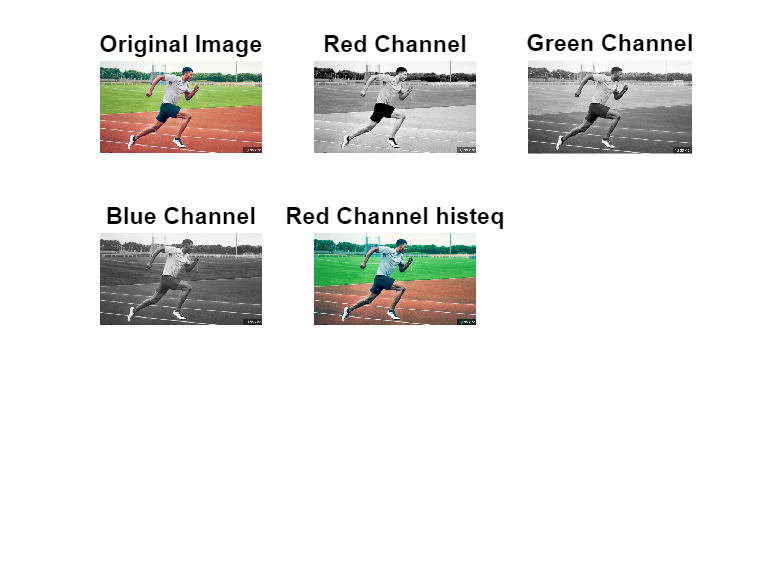

subplot(3,3,5);
R_histeq=histeq(R);
new_img = cat(3,R_histeq,G,B);
imshow(new_img);
title('Red Channel histeq');

imadjust() applied to the green channel

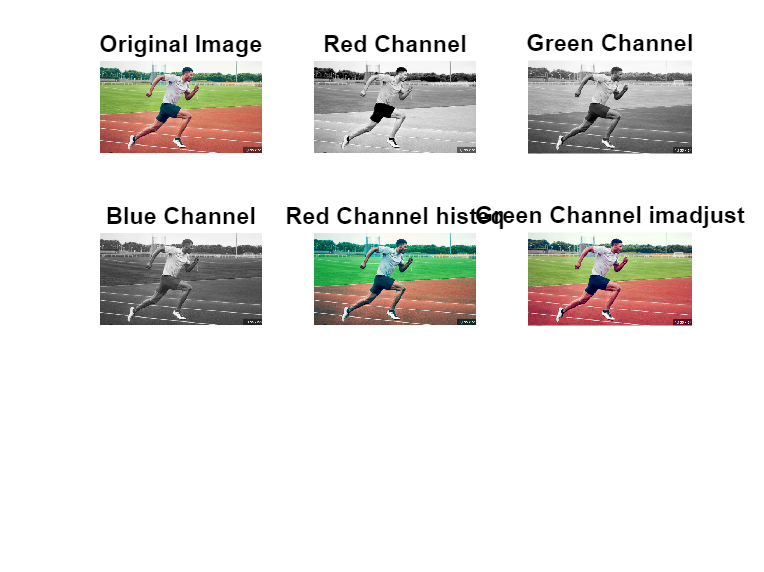

subplot(3,3,6);
G_imadjust=imadjust(G);
new_img = cat(3,R,G_imadjust,B);
imshow(new_img);
title('Green Channel imadjust');

adapthisteq applied to the green channel

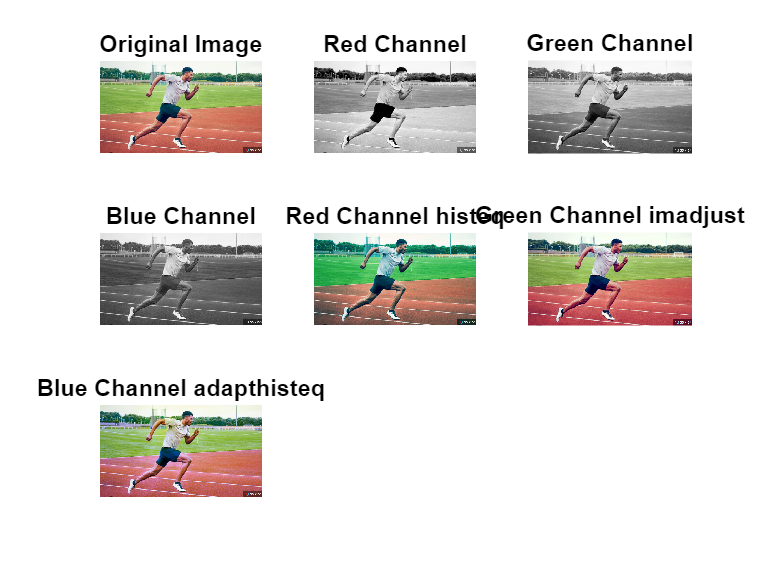

subplot(3,3,7);
B_adapthisteq=adapthisteq(B);
new_imgB = cat(3,R,G,B_adapthisteq);
imshow(new_imgB);
title('Blue Channel adapthisteq');